# Classify Product Reviews Using Convolutional Neural Network

To classify text data using Convolutional Neural Network, the text must be converted to image. Reviews are padded or truncated to a constant length *S* and then converted into sequences of word vectors of length *C* using a word embedding. The reviews are now represented as 1-by-*S*-by-*C* image - an image with height 1, width *S*, and *C* depth.

This code trains a network with 1-D convolutional filters of varying widths. The width of each filter corresponds to an n-gram length of words. The network has multiple branches of convolutional layers, so it can use different n-gram lengths. 

clearvars % clear variables from workspace

**Variables for tweaking**

sql = 128;                      % sequence length
nf = 512;                       % number of filters
ngl = [1 2 3 4 5];   %ngramlengths
mbs = 512;                                 % mini batch size
me = 12;                   % maximum number of epochs during training
ilr = 0.05;                    % learning rate, defaultis .001 for ADAM
vf = 1;                         % validation frequency for training data
do = 0.0;                       % Drop out probability for drop out layer
str = [1 1];                    % define filter stride; Matlab default is 1 horizontal 1 vertical
gdf = 0.9;      % set gradient decay factor for use in training options
sgdf = 0.9;     % set value for squared gradient factor for use in training options - 0.99 to 0.9
p = 0.1;         % Set pecentage for training
lrdf = 0.5;         % Learn rate drop factor drop by a factor of 0.5
lrdp = 5;          % Learn rate drop period - every 10 epochs
l2r = 0.0005;        % Regularization to limit overfitting


## Load Pretrained Word Embedding

Load the pretrained fastText word embedding. This function requires the Text Analytics Toolbox™ Model *for fastText English 16 Billion Token Word Embedding* support package. 

emb = fastTextWordEmbedding;
numFeatures = emb.Dimension;

## Load Data

Create a tabular text datastore from the training data. Read the data from the `"comments text"` and `"labeled"` columns only.

ReadTrain = "PowerFurniture_Train.csv";
data = readtable(ReadTrain,"VariableNamingRule","preserve");

Read the labels from the data and find the unique class names.

% Categorize data labels
DataLabels = data{:, "RecallStatus"};
classNames = unique(DataLabels);
DataLabels_Categorical = categorical(DataLabels,classNames);
numObservations = numel(DataLabels);

% Extract text of reviews
ReviewText = data{:, "ReviewText"};

## Preprocess Text

% Tokenize the text.
documents = tokenizedDocument(ReviewText);

% Convert the text to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove tokens containing digits.
pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
documents = replace(documents,pat,"");

% Stem and lemmatize
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Fix mis-spelled words
documents = correctSpelling(documents);

% Remove 1 character words
documents = removeShortWords(documents, 1)

documents =   8749×1 tokenizedDocument:

     17 tokens: work great keep scooter upright trip free nothing like scooter ankle broken sprain ankle ground highly recommend
     13 tokens: great two year old small year old old easy assemble great value price
     22 tokens: get down put last drawer together find manufacturer drill hole incorrectly drawer side late send back drawer tacky need item week ago
      6 tokens: beautiful perfect size love great price
     76 tokens: even bad review decide go against gut purchase dresser grant cheap tax come around put almost dresser together notice drawer side miss tempt take dresser back whole part get replacement hopefully part need package specify miss part contact company try replacement part order online luck keep tell part incorrect way stupid call number type still wait hold minute feel like wait IRS cheap dresser save purchase expensive may well purchase same price

Prepare documents for sizing to fit CNN

Converts data into a table containing the predictors and the responses. The predictors are 1-by-`sequenceLength`-by-*C* arrays of word vectors given by the word embedding `emb`, where *C* is the embedding dimension. The responses are categorical labels over the classes in `classNames`.

% Convert documents to embeddingDimension-by-sequenceLength-by-1 images.
predictors = doc2sequence(emb,documents,'Length',sql, "UnknownWord","discard","PaddingDirection","right")

predictors = 8749×1 cell array
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}



% Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
predictors = cellfun(@(X) permute(X,[3 2 1]),predictors,'UniformOutput',false);

% TRAINING AND VALIDATION 

% Partition data
C1 = DataLabels_Categorical;

Data_PreProcessed = table;
Data_PreProcessed.Predictors = predictors;
Data_PreProcessed.Responses = C1;

cvp = cvpartition(Data_PreProcessed.Responses,'Holdout',p);
dataValidation = Data_PreProcessed(test(cvp),:);
dataTrain = Data_PreProcessed(training(cvp),:);

## Define Network Architecture

Define the network architecture for the classification task.

The following steps describe the network architecture.

- Specify an input size of 1-by-*S*-by-*C*, where *S* is the sequence length and *C* is the number of features (the embedding dimension).

- For the n-gram lengths 2, 3, 4, and 5, create blocks of layers containing a convolutional layer, a batch normalization layer, a ReLU layer, a dropout layer, and a max pooling layer.

- For each block, specify 200 convolutional filters of size 1-by-*N* and pooling regions of size 1-by-*S*, where *N* is the n-gram length.

- Connect the input layer to each block and concatenate the outputs of the blocks using a depth concatenation layer.

- To classify the outputs, include a fully connected layer with output size *K*, a softmax layer, and a classification layer, where *K* is the number of classes.

First, in a layer array, specify the input layer, the first block for unigrams, the depth concatenation layer, the fully connected layer, the softmax layer, and the classification layer.

inputSize = [1 sql numFeatures];

numBlocks = numel(ngl);

numClasses = numel(classNames);

Create a layer graph containing the input layer. Set the normalization option to `'none'` and the layer name to `'input'`.

layer = imageInputLayer(inputSize,'Normalization','none','Name','input'); %what does setting the ormalization to none do?
lgraph = layerGraph(layer);

For each of the n-gram lengths, create a block of convolution, batch normalization, ReLU, dropout, and max pooling layers. Connect each block to the input layer.

for j = 1:numBlocks
    N = ngl(j);
    
    block = [
        convolution2dLayer([1 N],nf,'Name',"conv"+N,...
                            'Padding','same',...
                            "WeightsInitializer","he",...
                            "Stride",str,...
                            "BiasInitializer","narrow-normal")
        batchNormalizationLayer('Name',"bn"+N)
        reluLayer('Name',"relu"+N)
        dropoutLayer(do,'Name',"drop"+N)
        maxPooling2dLayer([1 sql],'Name',"max"+N)];
    
    lgraph = addLayers(lgraph,block);
    lgraph = connectLayers(lgraph,'input',"conv"+N);
end

View the network architecture in a plot.

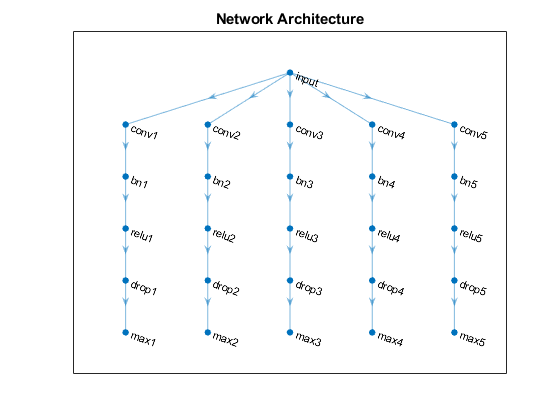

figure
plot(lgraph)
title("Network Architecture")

Add the depth concatenation layer, the fully connected layer, the softmax layer, and the classification layer. 

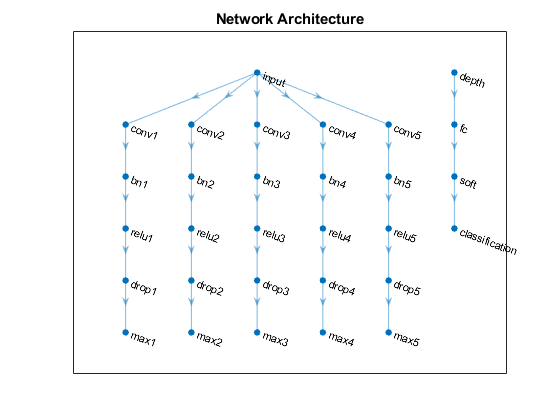

layers = [
    depthConcatenationLayer(numBlocks,'Name','depth')
    fullyConnectedLayer(numClasses,'Name','fc',"WeightsInitializer","he")
    softmaxLayer('Name','soft')
    classificationLayer('Name','classification')];
    
lgraph = addLayers(lgraph,layers);

figure
plot(lgraph)
title("Network Architecture")

Connect the max pooling layers to the depth concatenation layer and view the final network architecture in a plot.

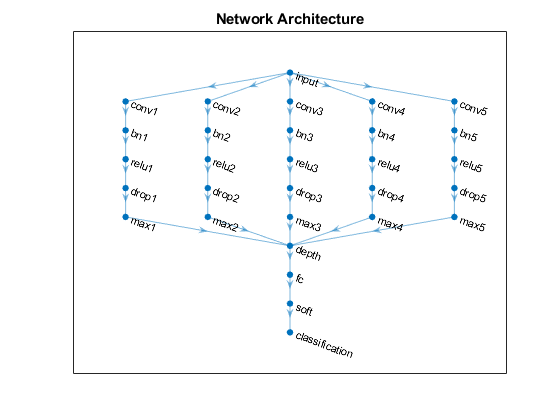

for j = 1:numBlocks
    N = ngl(j);
    lgraph = connectLayers(lgraph,"max"+N,"depth/in"+j);
end

figure
plot(lgraph)
title("Network Architecture")

## Train Network

Specify the training options:

- Train with a mini-batch size of 128.

- Do not shuffle the data because the datastore is not shuffleable.

- Display the training progress plot and suppress the verbose output.

Define training options

numIterationsPerEpoch = floor(numObservations/mbs);

options = trainingOptions('adam', ... 
    'MiniBatchSize',mbs, ...
    'Shuffle','every-epoch', ... 
    'GradientDecayFactor', gdf, ...
    'SquaredGradientDecayFactor', sgdf, ...
    'MaxEpochs', me, ...
    'Plots','training-progress', ...
    'InitialLearnRate', ilr, ... 
    'LearnRateDropFactor', lrdf, ...
    'LearnRateDropPeriod', lrdp, ...
    "ValidationData",dataValidation, ...
    "ValidationFrequency",vf, ...
    "L2Regularization", l2r, ...
    "LearnRateSchedule","piecewise", ...
    'Verbose',false); 

Train the network using the `trainNetwork` function.

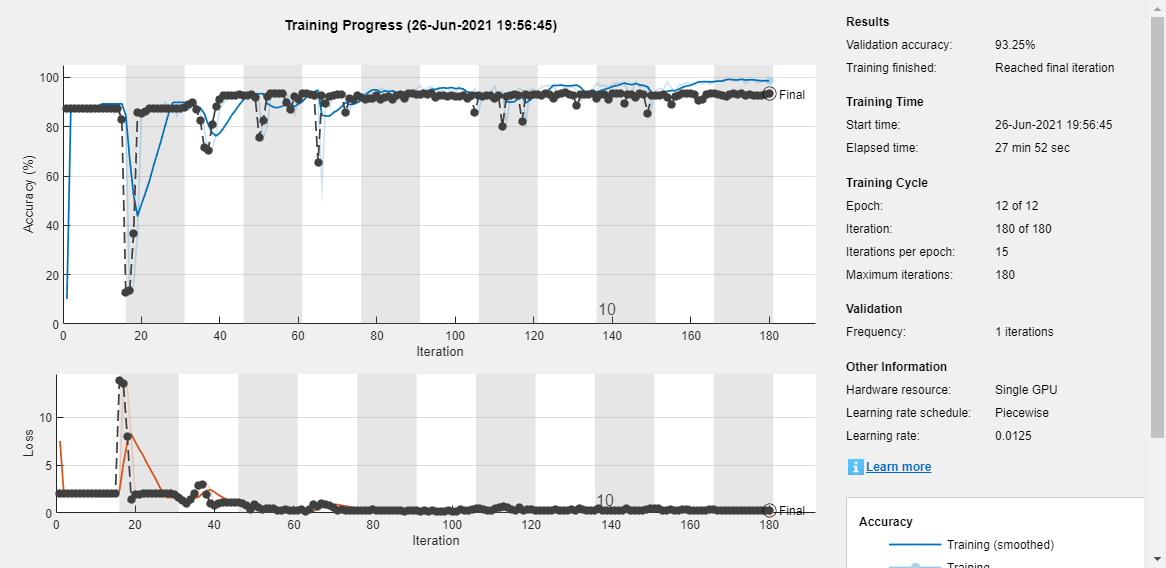

net = trainNetwork(dataTrain,lgraph,options);

## Predict Using New Data

Create a table containing the test reviews.

ReadTest = "PowerFurniture_Test.csv";
DataTest = readtable(ReadTest,"VariableNamingRule","preserve");
ReviewsTest = DataTest{:, "ReviewText"}

ReviewsTest = 987×1 cell array
    {'High quality for the price'                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

## Preprocess Text

% Tokenize the text.
documents = tokenizedDocument(ReviewsTest);

% Convert the text to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

% Remove tokens containing digits.
pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
documents = replace(documents,pat,"");

% Stem and lemmatize
documents = addPartOfSpeechDetails(documents);
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');

% Fix mis-spelled words
documents = correctSpelling(documents);

% Remove 1 character words
documents = removeShortWords(documents, 1)

documents =   987×1 tokenizedDocument:

      3 tokens: high quality price
      6 tokens: great product easy put together myself
      4 tokens: great product son love
     42 tokens: give star son sou excited purchase bay death family hadn't get around put together finally get normalcy life decide put together today minute wheel pop completely off ride leave little pellet everywhere go look online replacement wheel product itself even ridiculous return
      5 tokens: toddler love chair great value
     10 tokens: price get good drawer stick time sturdy go wrong price
     19 tokens: nice balance bike price aware tiny just right two half year old petite side way work tall year old
     49 tokens: new granddaughter love bouncer able assemble minimum effort instruction clear activity bar high young baby able supplement low activity bar previous small bouncer replace same company disappoint mirror activity bar old

Prepare documents for sizing to fit CNN

Converts data into a table containing the predictors and the responses. The predictors are 1-by-`sequenceLength`-by-*C* arrays of word vectors given by the word embedding `emb`, where *C* is the embedding dimension. The responses are categorical labels over the classes in `classNames`.

% Convert documents to embeddingDimension-by-sequenceLength-by-1 images.
documents = doc2sequence(emb,documents,'Length',sql, "UnknownWord","discard","PaddingDirection","right")

documents = 987×1 cell array
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}
    {300×128 single}



% Reshape images to be of size 1-by-sequenceLength-embeddingDimension.
documents = cellfun(@(X) permute(X,[3 2 1]),documents,'UniformOutput',false);

Classify the new sequences using the trained Convolution Neural Network.

XNew = table;
XNew.Predictors = documents;
labelsNew = classify(net,XNew);
XNew.Responses = DataTest(:, "RecallStatus");
XNew.Predictions = labelsNew;

Check Accuracy

labelsTrue = categorical(DataTest{:, "RecallStatus"});
AccuracyCNN = sum(labelsTrue == labelsNew)/numel(labelsTrue == labelsNew)

AccuracyCNN = 0.9352

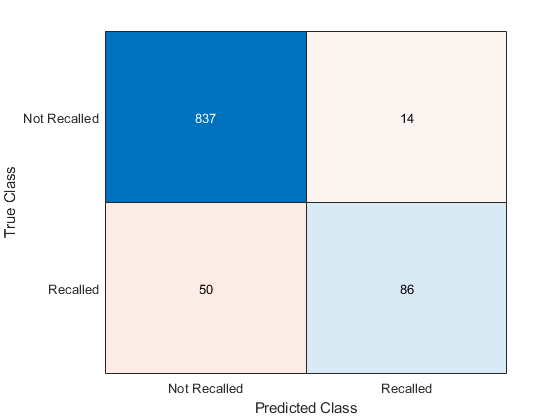

confusionchart(labelsTrue, labelsNew)


DataTest.Predictions = labelsNew;
filenameWrite = 'TroubleshootTest.xlsx';
writetable(DataTest,filenameWrite);

Investigate model statistics

- Precision=TP / (TP + FP)

- Recall= TP / (TP + FN)

- F-score = 2*TP /(2*TP+ FP + FN)

- False Positive – Type 1 Error

- False Negative – Type 2 Error

cm = confusionmat(labelsTrue, labelsNew);

NRTP = cm(1);
NRFP = cm(2);
NRTN = cm(4);
NRFN = cm(3);

RTP = cm(4);
RFP = cm(3);
RTN = cm(1);
RFN = cm(2);

accuracy_cm = [(NRTP+NRTN)/(NRTP+NRTN+NRFP+NRFN); (RTP+RTN)/(RTP+RTN+RFP+RFN)]

accuracy_cm =     0.9352
    0.9352


overall_accuracy = mean(accuracy_cm)

overall_accuracy = 0.9352


precision_cm = diag(cm)./sum(cm,2)

precision_cm =     0.9835
    0.6324


overall_precision = mean(precision_cm)

overall_precision = 0.8080


recall_cm = diag(cm)./sum(cm,1)'

recall_cm =     0.9436
    0.8600


overall_recall = mean(recall_cm)   

overall_recall = 0.9018


fscore_cm = 2*diag(cm)./(sum(cm,2) + sum(cm,1)')

fscore_cm =     0.9632
    0.7288


overall_fscore = mean(fscore_cm)

overall_fscore = 0.8460


[accuracy_cm precision_cm recall_cm fscore_cm; overall_accuracy overall_precision overall_recall overall_fscore]

ans =     0.9352    0.9835    0.9436    0.9632
    0.9352    0.6324    0.8600    0.7288
    0.9352    0.8080    0.9018    0.8460


## Preprocess Text Function

The `preprocessTextData` function takes text data, a sequence length, and a word embedding and performs these steps:

- Tokenize the text.

- Convert the text to lowercase.

- Converts the documents to sequences of word vectors of the specified length using the embedding.

- Reshapes the word vector sequences to input into the network.

function PreProcesedReviews = preprocessReviews(ReviewText)

    % Tokenize the text.
    documents = tokenizedDocument(ReviewText);
    
    % Convert the text to lowercase.
    documents = lower(documents);
    
    % Erase punctuation.
    documents = erasePunctuation(documents);
    
    % Remove tokens containing digits.
    pat = textBoundary + wildcardPattern + digitsPattern + wildcardPattern + textBoundary;
    documents = replace(documents,pat,"");
    
    % Stem and lemmatize
    documents = addPartOfSpeechDetails(documents);
    documents = removeStopWords(documents);
    documents = normalizeWords(documents,'Style','lemma');
    
    % Fix mis-spelled words
    documents = correctSpelling(documents);
    
    % Remove 1 character words
    documents = removeShortWords(documents, 1);
    
    % Assign function output
    PreProcesedReviews = documents;
end

*Copyright 2018 The MathWorks, Inc.*